# Comparing CSI-RS results with NeoRadium

% To save a new set of files, you need to set the saveFiles to true.

saveFiles = true;
outPath = fileparts(matlab.desktop.editor.getActiveFilename);
disp(outPath);

/Users/shahab/code/Fireball/OpenSource/onGithub/Tests/Wireless/NewProject/OnGit/neoradium/Playground/CompareWithMatlab/CSI-RS/MatlabFiles


## Initialize Carrier abd CSI-RS objects 

Create a carrier configuration object representing a 5 MHz carrier with subcarrier spacing of 15 kHz.

carrier = nrCarrierConfig;
carrier.NSizeGrid = 25;
carrier.SubcarrierSpacing = 15;
carrier.NSlot = 1;
carrier.NFrame = 0

carrier =   nrCarrierConfig with properties:

                NCellID: 1
      SubcarrierSpacing: 15
           CyclicPrefix: 'normal'
              NSizeGrid: 25
             NStartGrid: 0
                  NSlot: 1
                 NFrame: 0
    IntraCellGuardBands: [0×2 double]

   Read-only properties:
         SymbolsPerSlot: 14
       SlotsPerSubframe: 1
          SlotsPerFrame: 10


Create a CSI-RS configuration object representing two CSI-RS resources, NZP with row number 3 and ZP with row number 5.

csirs = nrCSIRSConfig;
csirs.CSIRSType = {'nzp','zp'};
csirs.CSIRSPeriod = {[5 1],[5 1]};
csirs.Density = {'one','one'};
csirs.RowNumber = [3 5];
csirs.SymbolLocations = {1,6};
csirs.SubcarrierLocations = {6,4};
csirs.NumRB = 25

csirs =   nrCSIRSConfig with properties:

              CSIRSType: {'nzp'  'zp'}
            CSIRSPeriod: {[5 1]  [5 1]}
              RowNumber: [3 5]
                Density: {'one'  'one'}
        SymbolLocations: {[1]  [6]}
    SubcarrierLocations: {[6]  [4]}
                  NumRB: 25
               RBOffset: 0
                    NID: 0

   Read-only properties:
          NumCSIRSPorts: [2 4]
                CDMType: {'FD-CDM2'  'FD-CDM2'}


Consider the power scaling of CSI-RS in dB.

powerCSIRS = 0;
disp(['CSI-RS power scaling: ' num2str(powerCSIRS) ' dB']);

CSI-RS power scaling: 0 dB


## Generate CSI-RS Symbols and Indices

Generate CSI-RS symbols for the specified carrier and CSI-RS configuration parameters. Apply power scaling.

sym = nrCSIRS(carrier,csirs);
csirsSym = sym*db2mag(powerCSIRS);
if (saveFiles)
    save(strcat(outPath,'/csirsSym.mat'),'csirsSym');
end
csirsSym(201:210)

ans =    0.7071 + 0.7071i
  -0.7071 + 0.7071i
   0.7071 + 0.7071i
   0.7071 + 0.7071i
   0.7071 + 0.7071i
   0.7071 + 0.7071i
   0.7071 - 0.7071i
  -0.7071 + 0.7071i
   0.7071 + 0.7071i
   0.7071 + 0.7071i


The variable `csirsSym` is a column vector containing CSI-RS symbols.

Generate CSI-RS indices for the specified carrier and CSI-RS configuration parameters.

csirsInd = nrCSIRSIndices(carrier,csirs);

The variable `csirsInd` is also a column vector of same size as that of `csirsSym`.

When you configure both ZP and NZP resources, the generation of ZP signals takes priority over the generation of NZP signals.

## Initialize Carrier Grid

Initialize the carrier resource grid for one slot.

ports = max(csirs.NumCSIRSPorts);   % Number of antenna ports
txGrid = nrResourceGrid(carrier,ports);
size(txGrid)

ans =    300    14     4


## Map CSI-RS Symbols Onto Carrier Grid

Perform resource element mapping.

txGrid(csirsInd) = csirsSym;
if (saveFiles)
    save(strcat(outPath,'/txGrid.mat'),'txGrid');
end
size(txGrid)

ans =    300    14     4


txGrid(128,:,1)'

ans =    0.0000 + 0.0000i
  -0.7071 + 0.7071i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


## Perform OFDM Modulation

Perform OFDM modulation to generate the time-domain waveform.

[txWaveform,ofdmInfo] = nrOFDMModulate(carrier,txGrid, "Nfft",2048);
if (saveFiles)
    save(strcat(outPath,'/txWaveform.mat'),'txWaveform');
end
size(txWaveform)

ans =        30720           4


txWaveform(3001:3010,1)

ans =    0.0017 - 0.0022i
   0.0027 - 0.0026i
   0.0038 - 0.0027i
   0.0048 - 0.0026i
   0.0054 - 0.0023i
   0.0055 - 0.0019i
   0.0051 - 0.0015i
   0.0042 - 0.0013i
   0.0028 - 0.0012i
   0.0012 - 0.0013i


## Pass Time-Domain Waveform Through Channel and Add AWGN Noise

Configure the number of receiving antennas.

R = 4;

Configure the channel.

channel = nrCDLChannel;
channel.SampleRate = 30720000;
channel.DelayProfile = 'CDL-D';
channel.DelaySpread = 10e-9;
channel.CarrierFrequency = 4e9;
channel.MaximumDopplerShift = 10;
channel.AngleScaling = true;
channel.MeanAngles = [130 70 80 110];
channel.RandomStream = 'Global stream';             % Use this to be able to match the random numbers in python
 
channel.TransmitAntennaArray.Size = [1 2 2 1 1];    % 2x2 antenna panel
% channel.TransmitAntennaArray.Element = '38.901';
channel.TransmitArrayOrientation = [10; 20; 30];    % Transmit antenna orientation bearing(α), downtilt(β), and slant(γ) angles in degrees

channel.ReceiveAntennaArray.Size = [1 2 2 1 1];     % 2x2 antenna
channel.ReceiveAntennaArray.Element = '38.901'      % Make sure we are using 3GPP antennas. (Default is not 3GPP)

channel =   nrCDLChannel with properties:

                 DelayProfile: 'CDL-D'
                 AngleScaling: true
                 AngleSpreads: [5 11 3 3]
                   MeanAngles: [130 70 80 110]
                  DelaySpread: 1.0000e-08
             CarrierFrequency: 4.0000e+09
          MaximumDopplerShift: 10
          UTDirectionOfTravel: [2×1 double]
               KFactorScaling: false
                   SampleRate: 30720000
         TransmitAntennaArray: [1×1 struct]
     TransmitArrayOrientation: [3×1 double]
          ReceiveAntennaArray: [1×1 struct]
      ReceiveArrayOrientation: [3×1 double]
           NormalizePathGains: true
                SampleDensity: 64
                  InitialTime: 0
                 RandomStream: 'Global stream'
      NormalizeChannelOutputs: true
             ChannelFiltering: true
    TransmitAndReceiveSwapped: false


chInfo = info(channel)

chInfo = struct with fields:
    KFactorFirstCluster: 13.3000
           ClusterTypes: {'LOS'  'NLOS'  'NLOS'  'NLOS'  'NLOS'  'NLOS'  'NLOS'  'NLOS'  'NLOS'  'NLOS'  'NLOS'  'NLOS'  'NLOS'  'NLOS'}
             PathDelays: [0 0 3.5000e-10 6.1200e-09 1.3630e-08 1.4050e-08 1.8040e-08 2.5960e-08 1.7750e-08 4.0420e-08 7.9370e-08 9.4240e-08 9.7080e-08 1.2525e-07]
       AveragePathGains: [-0.2000 -13.5000 -18.8000 -21 -22.8000 -17.9000 -20.1000 -21.9000 -22.9000 -27.8000 -23.6000 -24.8000 -30 -27.7000]
              AnglesAoD: [0 0 89.2000 89.2000 89.2000 13 13 13 34.6000 -64.5000 -32.9000 52.6000 -132.1000 77.2000]
              AnglesAoA: [-180 -180 89.2000 89.2000 89.2000 163 163 163 -137 74.5000 127.7000 -119.6000 -9.1000 -83.8000]
              AnglesZoD: [98.5000 98.5000 85.5000 85.5000 85.5000 97.5000 97.5000 97.5000 98.5000 88.4000 91.3000 103.8000 80.3000 86.5000]
              AnglesZoA: [81.5000 81.5000 86.9000 86.9000 86.9000 79.4000 79.4000 79.4000 78.2000 73.6000 78.3000 87 7

Based on the configured channel, append zeros to the transmitted waveform to account for the channel delay.

maxChDelay = ceil(max(chInfo.PathDelays*channel.SampleRate)) + chInfo.ChannelFilterDelay

maxChDelay = 11

txWaveform = [txWaveform; zeros(maxChDelay,size(txWaveform,2))];

Pass waveform through channel.

rng(123);  % For Reproducibility (Making sure the same random numbers are used by Matlab and NeoRadium)
[rxWaveform,pathGains,sampleTimes] = channel(txWaveform);
if (saveFiles)
    save(strcat(outPath,'/rxWaveform.mat'),'rxWaveform')
end
rxWaveform(3001:3010,1)

ans = 1.0e-04 *

   0.9289 - 0.2171i
   0.8570 - 0.2027i
   0.7425 - 0.1585i
   0.5847 - 0.1025i
   0.3894 - 0.0543i
   0.1685 - 0.0308i
  -0.0619 - 0.0440i
  -0.2830 - 0.0981i
  -0.4772 - 0.1885i
  -0.6296 - 0.3025i


To produce the actual propagation channel `H_actual`, perform perfect channel estimation.

pathFilters = getPathFilters(channel);
offset = nrPerfectTimingEstimate(pathGains,pathFilters)

offset = 7

NRB = 25;
SCS = 15;
nSlot = 0;
H_actual = nrPerfectChannelEstimate(pathGains,pathFilters,...
    NRB,SCS,nSlot,offset,sampleTimes,"Nfft",2048);
if (saveFiles)
    save(strcat(outPath,'/H_actual.mat'),'H_actual')
end

Add AWGN noise to the waveform. For an explanation of the SNR definition that this example uses, see [SNR Definition used in Link Simulations](docid:5g_ug#mw_37cef3ca-2f4b-433d-8d68-117a881ca5fd).

% Use the following to generate random noise
SNRdB = 50;           % in dB
SNR = 10^(SNRdB/10);  % Linear value
N0 = 1/sqrt(2.0*R*double(ofdmInfo.Nfft)*SNR); % Noise variance
rng(0);
noise = N0*complex(randn(size(rxWaveform)),randn(size(rxWaveform)));
if (saveFiles)
    save(strcat(outPath,'/noise.mat'),'noise')
end
% noise=load(strcat(outPath,'/noise.mat')).noise;
rxWaveform = rxWaveform + noise;

Perform timing synchronization using NZP-CSI-RS. To estimate timing offset, use `nrTimingEstimate` and consider the NZP-CSI-RS as a reference.

% Disable ZP-CSI-RS resource, not going to be used for timing and channel
% estimation
csirs.CSIRSPeriod = {[5 1],'off'};
% Generate reference symbols and apply power scaling
refSym = db2mag(powerCSIRS)*nrCSIRS(carrier,csirs);
% Generate reference indices
refInd = nrCSIRSIndices(carrier,csirs);
offset = nrTimingEstimate(carrier,rxWaveform,refInd,refSym,"Nfft",2048)

offset = 7

rxWaveform = rxWaveform(1+offset:end,:);

OFDM demodulate the received time-domain waveform.

rxGrid = nrOFDMDemodulate(carrier,rxWaveform,"Nfft",2048); % Of size K-by-L-by-R
if (saveFiles)
    save(strcat(outPath,'/rxGrid.mat'),'rxGrid')
end
size(rxGrid)

ans =    300    14     4


rxGrid(121,:,1)'

ans =   -0.0026 + 0.0018i
  -0.0011 + 0.0013i
  -0.0001 + 0.0010i
   0.0008 - 0.0010i
   0.0004 + 0.0015i
  -0.0013 - 0.0012i
  -0.0010 - 0.0005i
  -0.0003 - 0.0002i
   0.0009 + 0.0001i
  -0.0016 + 0.0006i


## Compare Estimated Channel Against Actual Channel

Perform practical channel estimation using NZP-CSI-RS. Make sure the CSI-RS symbols `csirsSym` are of the same CDM type.

cdmLen = [2 1]; % Corresponds to CDMType = 'FD-CDM2'
[H_est,nVar] = nrChannelEstimate(carrier,rxGrid,refInd,refSym,'CDMLengths',cdmLen);
size(H_est)

ans =    300    14     4     2


estSNR = -10*log10(nVar);
disp(['estimated SNR = ' num2str(estSNR) ' dB'])

estimated SNR = 54.4939 dB


Plot the estimated channel and actual channel between first transmitting antenna and first receiving antenna.

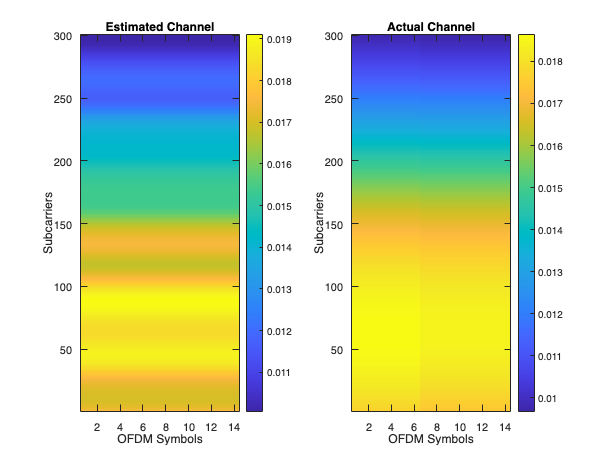

figure;

% Plot the estimated channel
subplot(1,2,1)
imagesc(abs(H_est(:,:,1,1)));
colorbar;
title('Estimated Channel')
axis xy;
xlabel('OFDM Symbols');
ylabel('Subcarriers');

% Plot the actual channel
subplot(1,2,2)
imagesc(abs(H_actual(:,:,1,1)));
colorbar;
title('Actual Channel')
axis xy;
xlabel('OFDM Symbols');
ylabel('Subcarriers');

Calculate the channel estimation error.

H_err = (H_est - H_actual(:,:,:,1:size(H_est,4)));
[minErr,maxErr] = bounds(abs(H_err),'all');
disp(['Absolute value of the channel estimation error is in the range of [' num2str(minErr) ', ' num2str(maxErr) ']'])

Absolute value of the channel estimation error is in the range of [7.2942e-06, 0.0024867]


## Local Functions

function plotGrid(gridSize,csirsInd,csirsSym)
%    plotGrid(GRIDSIZE,CSIRSIND,CSIRSSYM) plots the carrier grid of size GRIDSIZE
%    by populating the grid with CSI-RS symbols using CSIRSIND and CSIRSSYM.

    figure()
    cmap = colormap(gcf);
    chpval = {20,2};
    chpscale = 0.25*length(cmap); % Scaling factor

    tempSym = csirsSym;
    tempSym(tempSym ~= 0) = chpval{1}; % Replacing non-zero-power symbols
    tempSym(tempSym == 0) = chpval{2}; % Replacing zero-power symbols
    tempGrid = complex(zeros(gridSize));
    tempGrid(csirsInd) = tempSym;

    image(chpscale*tempGrid(:,:,1)); % Multiplied with scaling factor for better visualization
    axis xy;
    names = {'NZP CSI-RS','ZP CSI-RS'};
    clevels = chpscale*[chpval{:}];
    N = length(clevels);
    L = line(ones(N),ones(N),'LineWidth',8); % Generate lines
    % Index the color map and associate the selected colors with the lines
    set(L,{'color'},mat2cell(cmap( min(1+clevels,length(cmap) ),:),ones(1,N),3)); % Set the colors according to cmap
    % Create legend 
    legend(names{:});

    title('Carrier Grid Containing CSI-RS')
    xlabel('OFDM Symbols');
    ylabel('Subcarriers');
end